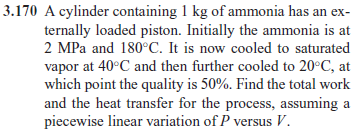

# symbolic units class

u = symunit;

# state 1 (superheated ammonia)

% ---------------------
% given
m1 = 1*u.kg;
p1 = 2*u.MPa;
T1 = 180*u.Celsius;
% ---------------------
% specific volume
v1 = 0.10571*u.m^3/u.kg;
% ---------------------
% specific internal energy
u1 = 1630.6*u.kJ/u.kg;
% ---------------------
% total volume
Vol1 = m1*v1;
% ---------------------

# state 2 (saturated vapor ammonia)

% ---------------------
% given
m2 = m1;
p2 = 1554.9*u.kPa;
T2 = 40*u.Celsius;
% ---------------------
% specific volume
v2 = 0.08313*u.m^3/u.kg;
% ---------------------
% specific internal energy
u2 = 1341.0*u.kJ/u.kg;
% ---------------------
% total volume
Vol2 = m2*v2;
% ---------------------

# state 3 (liquid-vapor ammonia mix)

% ---------------------
% given
m3 = m1;
p3 = 857.5*u.kPa;
T3 = 20*u.Celsius;
x3 = 0.50;
% ---------------------
% specific volume
vf3 = 0.001638*u.m^3/u.kg;
vfg3 = 0.14758*u.m^3/u.kg;
v3 = vf3+x3*vfg3;
% ---------------------
% specific internal energy
uf3 = 272.89*u.kJ/u.kg;
ufg3 = 1059.3*u.kJ/u.kg;
u3 = uf3+x3*ufg3;
% ---------------------
% total volume
Vol3 = m3*v3;
% ---------------------

# total work done

W_12 = rewrite((p1+p2)*(Vol2-Vol1)/2, u.kJ);
W_12_vpa = vpa(W_12, 4) %#ok

$$W\_12\_vpa = -40.13\,\mathrm{kJ}$$

W_23 = rewrite((p2+p3)*(Vol3-Vol2)/2, u.kJ);
W_23_vpa = vpa(W_23, 3) %#ok

$$W\_23\_vpa = -9.29\,\mathrm{kJ}$$

W_13 = W_12+W_23;
W_13_vpa = vpa(W_13, 4) %#ok

$$W\_13\_vpa = -49.42\,\mathrm{kJ}$$

clear W_12_vpa W_23_vpa W_13_vpa;

# total heat transfer

Q_12 = m2*u2-m1*u1+W_12;
Q_12_vpa = vpa(Q_12, 5) %#ok

$$Q\_12\_vpa = -329.73\,\mathrm{kJ}$$

Q_23 = m3*u3-m2*u2+W_23;
Q_23_vpa = vpa(Q_23, 5) %#ok

$$Q\_23\_vpa = -547.75\,\mathrm{kJ}$$

Q_13 = Q_12+Q_23;
Q_13_vpa = vpa(Q_13, 5) %#ok

$$Q\_13\_vpa = -877.48\,\mathrm{kJ}$$

clear Q_12_vpa Q_23_vpa Q_13_vpa;